# Normalization tester

Clear Matlab variables, close all the windows and applications and clear the command window

clear; close; clc;

Load an image

%% Sentinel-2 
% Bands -> [B1, B2 (B), B3 (G), B4 (R), B5, B6, B7, B8, B8A, B9, B10, B11, B12, QA10, QA20, QA60]
% Bands -> [1   2       3       4       5   6   7   8   9    10  11   12   13   14    15    16]
S2 = im2double(imread('data/image_RGB_135_Apr_patch_6.tif'));

Plot the image and the histogram before the normalization. In this case we are only selecting the bands 4, 3, 2 or R, G, B.

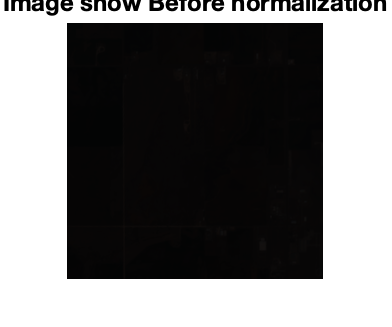

plotter(S2, [1 2 3], "Before normalization")

Then apply the min-max normalization and plot the image and the histogram

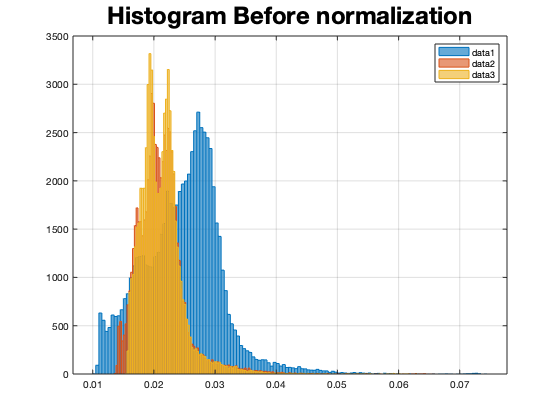

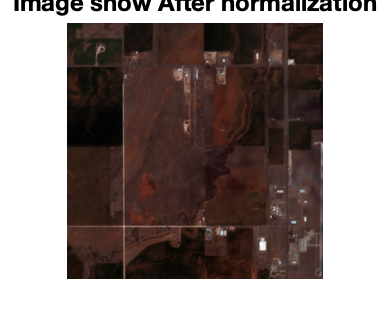

[S2, a, b, alpha, beta] = normalize_data(S2, 'min-max', 1, 0);

plotter(S2, [1,2,3], "After normalization")

Then apply the inverse function to restore the range

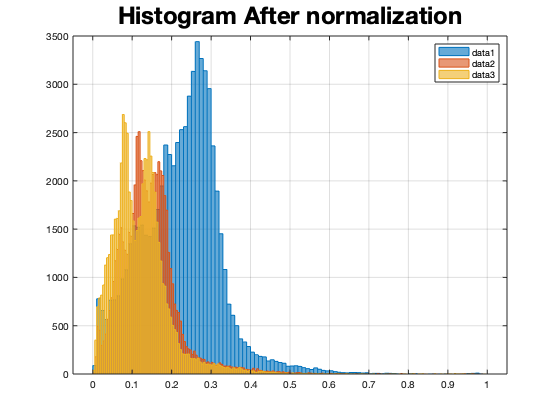

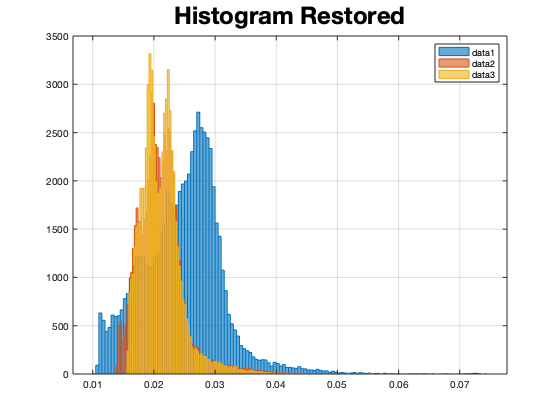

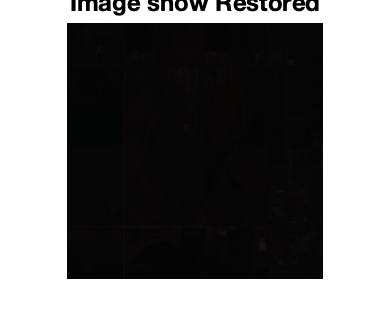

[restored_data] = restore_range(S2, 'min-max', a, b, alpha, beta);
plotter(restored_data, [1,2,3], "Restored")